# Linear Equation System and Plotting

#### Linear equation system

Step 1: Solve the equation system by storing the  ,  ,   independent variables into `xSolution` variable that satisfies the following linear equations:

                Eq. 1: 

                Eq. 2: 

                Eq. 3: 

% Create matrix representation of linear equation system:
A = [3, 2, 1;
     1, 2, 3;
     3, 1, 3];
b = [8, 12, 16]';
% Compute the solution of the linear equation system: 
xSolution = A\b

xSolution =     1.7500
   -0.5000
    3.7500


Step 2: Identify the number of variables in question programmatically and store the result to `numOfVariables`!

% Identify the number of variables in question programmatically:
numOfVariables = numel(xSolution);

Step 2: Checker whether `xSolution `is an exact solution of the linear equation system! Store the result into `isExactSolution` boolean variable having a logical true value if `xSolution` is assumed to be exact.

% Check whether the given solution is exact:
if rank(A) == length(xSolution)
    isExactSolution = true;

else
    isExactSolution = false;
end

#### Plotting

Step 1: Create `xVector` containing discrete *x* abscissa coordinates of following functions starting from 0 to 5 with 0.1 resolution!

xVector = 0:0.1:5;

Step 2: Create `yVectorQuadratic` containing discrete *y* values of function !

yVectorQuadratic = 2 * xVector.*xVector + 5;

Step 3: Create `yVectorSin `containing discrete *y* values of function  on the **same axis**!

yVectorSin = sin((2 * xVector) + pi / 6);

Step 4: Create a figure and axis object with `figureObject` and `axisObject` names!

figureObject = figure;
axisObject = axes(figureObject,FontSize=13)

axisObject =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


Step 5: Set the position of the figure's bottom left corner to [0.1 0.15] with respect to the screen size. Set the width and height of the figure to fill the 85% and 75% of the screen width and height, respectively! 

figureObject.Units = 'normalized';
figureObject.Position = [0.1, 0.15, 0.85, 0.75];

Step 6: Set the fontSize of the axis to 13! 

axisObject.FontSize = 13

axisObject =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


Step 7: Plot the  quadratic function with `blue` color, and set the **line width** to 1.5 and the line style to `dashed`!

plot(axisObject,xVector,yVectorQuadratic,'b--',LineWidth=1.5)
hold on;

Step 8: Plot the  trigonometric function with color given by [192 0 0] RGB code and with `circle` markers that have the same edge color and face color as the line! 

plot(axisObject,xVector,yVectorSin,'-o',Color=[192 0 0]/255 ...
    ,MarkerEdgeColor=[192 0 0]/255, MarkerFaceColor=[192 0 0]/255)

Step 9: Set the corresponding axis label to *x* and *y*! 

xlabel(axisObject, 'x');
ylabel(axisObject, 'y');

Step 10: Add legend to the axis with vertical alignment containing explaining the curve notations with 'Quadratic function' and 'Trigonometric function'! 

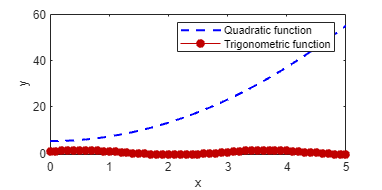

legend(axisObject,["Quadratic function","Trigonometric function"])